# **Analisi della Concentrazione di CO2 nell'Osservatorio di Mauna Loa**

In questo script viene mostrato il comportamento del fenomeno registrato nell'Osservatorio di Mauna Loa sulla concentrazione di CO2 nell'atmosfera. In input al problema è presente un file `"co2.mat" `nel quale sono memorizzate le misurazioni di CO2 di ogni mese. A tal proposito viene effettuato un grafico del comportamento del fenomeno e i relativi periodogrammi. Attraverso lo strumento "`FFT" (Trasformata di Fourier Discreta) `del Matlab si analizzano le frequenze e i periodi associati alla potenza. Inoltre viene determinato il picco di potenza in allegato al corrispondente indice e periodo. Infine vengono confrontati i risultati tra il fenomeno registrato e quello ricostruito con qualche modifica.

### Caricamento dei Dati Registrati

In questa sezione vengono caricati i dati registrati nella matrice "co2.mat", successivamente viene ricostruito il grafico delle misurazioni memorizzate.

load -ASCII co2.mat

N.B : Attraverso il comando "load -ASCII nomefile" si effettua il caricamento del file rimuovendo elementi non idonei al problema nonostante ciò. 

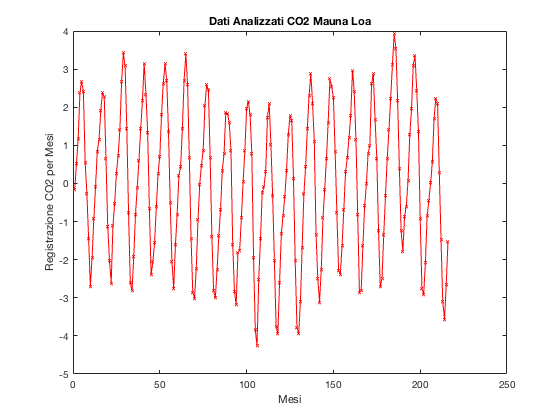

plot(co2(:,1),co2(:,2),'-xr','MarkerFaceColor','b','MarkerSize',2);
xlabel('Mesi');
ylabel('Registrazione CO2 per Mesi');
title('Dati Analizzati CO2 Mauna Loa');

### Grafico del Fenomeno e Periodogramma Relativo

Una volta mostrati i valori caricati attraverso il grafico, effettuiamo la "Trasformata di Fourier Discreta" per ottenere la trasposizione del fenomeno nel dominio delle frequenze. Rimuovendo la componente continua viene calcolata la potenza che ci consente di mostrare il periodogramma in termini di rapporto tra cicli e mesi che in termini di rapporto tra mesi e cicli sia per il Periodo che per le Frequenze.

Di seguito viene dunque richiamato uno script appositamente creato che effettua i calcoli.

*N.B : Lo script restituisce i parametri utili per i calcoli successivi.*

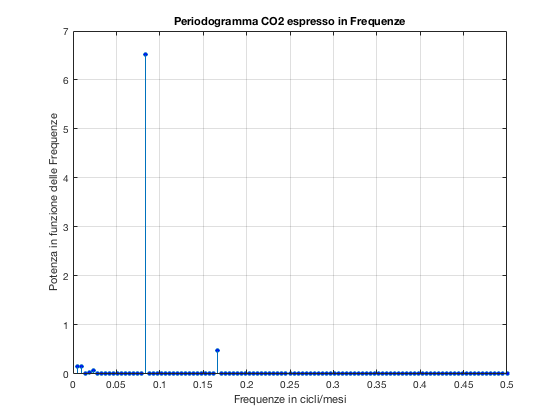

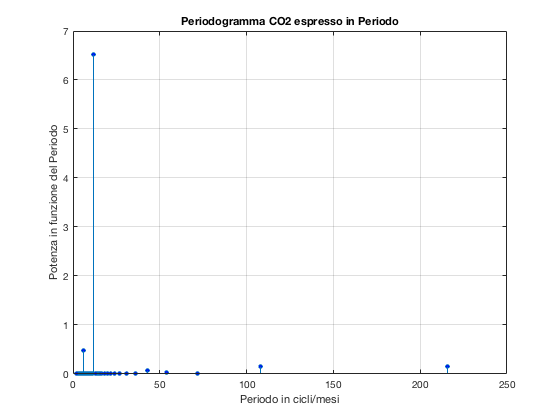

[comp_continua,potenza,freq,N,Y] = Show_Periodogram_CO2(co2);

### Calcolo dei Picchi di Massima Potenza

Una volta ricavati i valori necessari per mostrare i Periodogrammi in funzione della Frequenza e del Periodo, vengono effettuati dei rilevamenti sul picco massimo di frequenza ed il corrispondente indice e periodo. Questo risulta utile per determinare ulteriori risultati sul fenomeno registrato.

%Viene riordinato il vettore perche' il vettore potenza e relativo a valori
%disorganizzati
[pot_max,indice_max_pot] = sort(potenza,'descend');
%In uscita mostro i due picchi dei periodogrammi dove la prima componente e
%relativa al periodogramma in frequenza e la seconda al periodogramma dei
%periodi
pot_max(1:2)

ans =     6.5265
    0.4748


%Indici relativi, Frequenze e Periodi
indice_max_pot(1:2)

ans =     18
    36


f1 = freq(indice_max_pot(1))

f1 = 0.0833

f2 = freq(indice_max_pot(2))

f2 = 0.1667

t1 = 1./f1

t1 = 12

t2 = 1./f2

t2 = 6

### Ricostruzione Fenomeno a Partire dai Dati Raccolti

#### 1° Componente di Potenza Maggiore

Una volta ricavati i picchi di massima potenza con i relativi indici, frequenze e periodi, bisogna ricostruire la trasformata di fourier delle componenti relative a questi valori assieme alla componente continua della trasformata di partenza. Attraverso l'uso della Routine del Matlab `"Ifft" `si ricava la trasformata di fourier inversa e si mostra l'andamento della parte reale della stessa. In analogia si mostra anche l'andamento del fenomeno per confronto con la parte reale della trasformata di fourier inversa.

%Azzero le componenti della DFT tranne quelle relative alla potenza massima
Y(indice_max_pot(3:length(indice_max_pot)))=0;
%Per simmetria della Trasformata bisogna azzerare anche quelle relative
%alle frequenze negative
Y(N+1-indice_max_pot(3:length(indice_max_pot)))=0;
%Riaggiungo la componente continua alla trasformata
Y=[comp_continua;Y];
%Ricostruzione segnale con IDFT
IY=ifft(Y);
%Mostro la parte reale della trasformata
figure();
subplot(2,1,1)
plot(real(IY),'g')
title('Parte reale della Ricostruzione')

#### Confronto con il grafico di partenza del Fenomeno

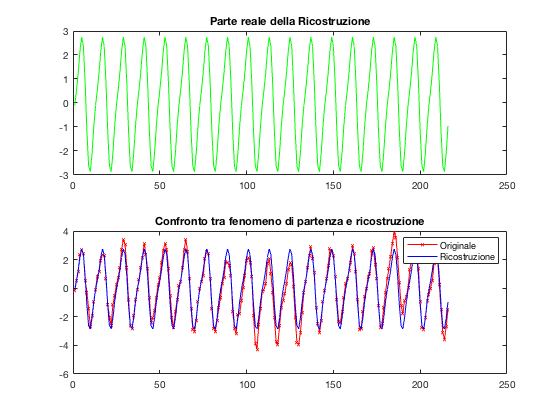

subplot(2,1,2)
plot(co2(:,1),co2(:,2),'-xr','MarkerFaceColor','b','MarkerSize',2);
hold on
plot(real(IY),'b');
hold off
legend('Originale','Ricostruzione')
title('Confronto tra fenomeno di partenza e ricostruzione')

#### 2° Componente di Potenza Maggiore

Rieseguiamo i calcoli andando a considerare anche le successive due componenti di potenza maggiore.

Y1 = fft(co2(:,2));
comp_continua2 = Y1(1);
Y1(1) = [];
Y1(indice_max_pot(5:length(indice_max_pot)))=0;
Y(N+1-indice_max_pot(5:length(indice_max_pot)))=0;
Y1=[comp_continua2;Y1];
IY1 = ifft(Y1);
figure();
subplot(2,1,1)
plot(real(IY1),'g')
title('Parte reale della Ricostruzione')

#### Confronto con il grafico di partenza del Fenomeno

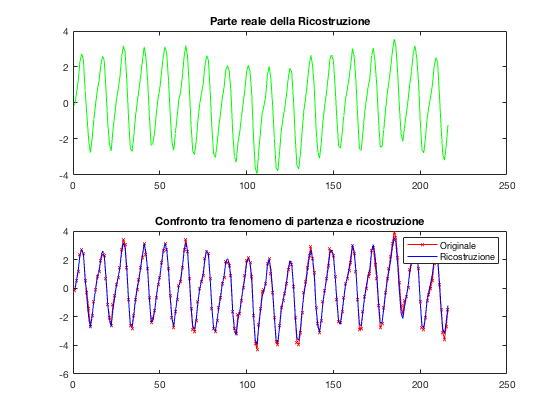

subplot(2,1,2)
plot(co2(:,1),co2(:,2),'-xr','MarkerFaceColor','b','MarkerSize',2);
hold on
plot(real(IY1),'b');
hold off
legend('Originale','Ricostruzione')
title('Confronto tra fenomeno di partenza e ricostruzione')

### Considerazioni

Si nota che  il segnale ricostruito utilizzando le 4 componenti relative alle potenze massime, rappresenta meglio il segnale originale rispetto a quello ottenuto utilizzado solo le prime due componenti di potenza massima.	

### Riferimenti

- [*Docenti.unina.it D'alessio Alessandra*](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

- [Trasformata di Fourier Discreta](https://it.wikipedia.org/wiki/Trasformata_discreta_di_Fourier)

### Autori

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***